% Solar Panel Parameters
P_max = 321; % Nominal power in Watts (NOCT)
I_NOCT = 800; % Light intensity at NOCT in W/m^2
panel_efficiency = 0.22; % Panel efficiency
temperature_coefficient = -0.0029; % Example: -0.29% per degree Celsius
T_ref = 20; % Reference temperature in °C (NOCT)

% Measured Data (example data)
I = [500, 600, 700, 800, 900, 1000, 950, 850, 750, 600]; % Light intensity in W/m^2
T_actual = [25, 26, 27, 28, 29, 30, 29, 28, 27, 26]; % Actual temperatures

dt = 1; % Time interval in hours (can be minutes, but ensure units match)

% Calculate Power Output
P = P_max * (I / I_NOCT); % Power generated at each time interval

% Adjust for Temperature
P = P .* (1 + temperature_coefficient * (T_actual - T_ref));

% Calculate Energy Output
E = sum(P) * dt; % Total energy in Watt-hours (Wh)

% Display Results
disp(['Total Energy Output: ', num2str(E), ' Wh']);

Total Energy Output: 3000.0941 Wh



% Plot Results
time = 1:length(I); % Assuming time intervals are uniform
figure;
plot(time, P, '-o');

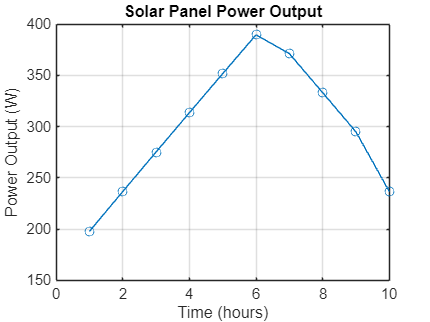

xlabel('Time (hours)');
ylabel('Power Output (W)');
title('Solar Panel Power Output');
grid on;